clear all 
clc

Загружаем данные из фала

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t1", "v1", "t2", "v2"];
opts.VariableTypes = ["double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Miror = readtable("зеркало.txt", opts);
TestMom = readtable("тест5мН.txt", opts);
Scan  = readtable("скан.txt", opts);
Stand = readtable("стенд.txt", opts);
%% Clear temporary variables
clear opts

i = 8500;

TestMomV = (TestMom.v2(400:i+399))+168;
MirorV = (Miror.v2(826:i+825))+150;
ScanV = (Scan.v2(537:i+536))+165;
StadV = (Stand.v2);


figure
p1 = plot(MirorV(1:i));
grid on
hold on
p2 = plot(ScanV(1:i));
xlabel("Время,с")
ylabel("''/c")
title("Скорость колебаний подвеса");
nt = 450

nt = 450

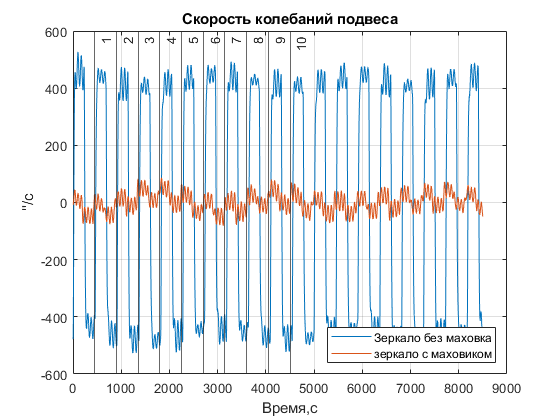

for i = 1:10
    xline(i*nt, '-', {i});
end
legend([p1 p2], {'Зеркало без маховка', 'зеркало с маховиком'}, "Location","southeast")
hold off

Прозводная моментов зеркала

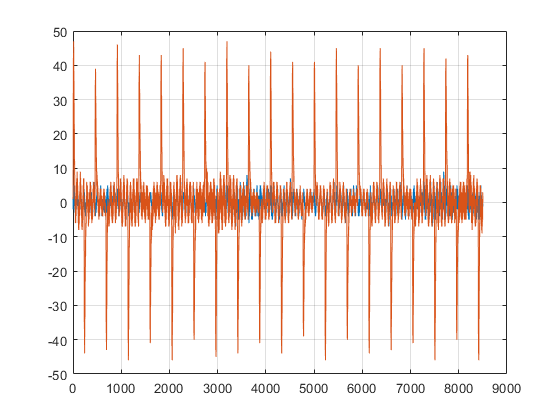

MirrorA = diff(MirorV);
ScanA = diff(ScanV);

figure
plot(ScanA);
grid on
hold on
plot(MirrorA);
hold off

Обработка измерений зеркала без маховика

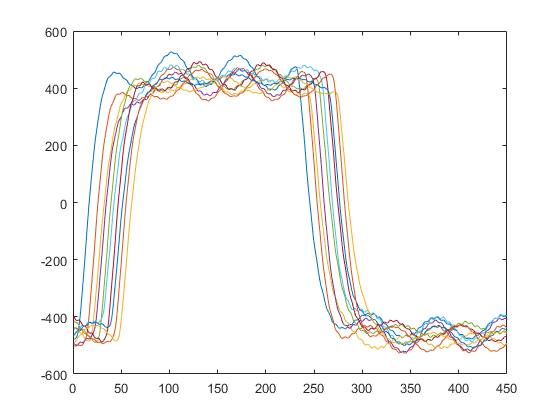


mz = zeros(nt,10);
mz(:,1) = MirorV(1 : nt);
%mt(:,1) = mt(:,1) + 124;
for i = 2 : 10
    mz(:,i) = MirorV(i*nt :i*nt+nt-1);
  %  mt(:,i) = mt(:,i) + abs(mt(1,i));
end

figure
plot(mz)
hold off

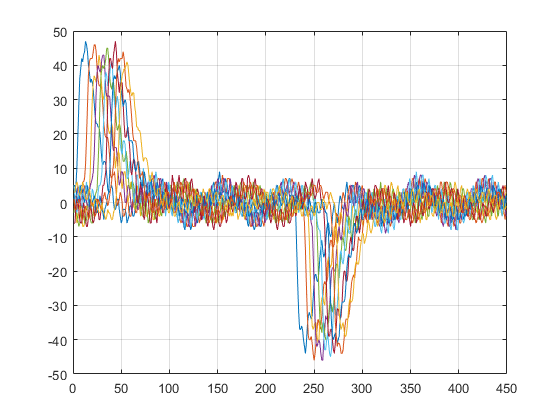


d_mz = diff(mz);

figure
plot(d_mz);
grid on

Максимальный момент в каждом измерении

max_d_mz = max(d_mz)

max_d_mz =     47    46    43    43    45    41    47    40    44    41


Математическое ожидание $\overset{-}{х} =\frac{1}{N}\bullet \sum_{i=1}^N x_i$

Mean_max_d_mz = mean(max_d_mz)

Mean_max_d_mz = 43.7000

Дисперсия 

Var_max_d_mz = var(max_d_mz)

Var_max_d_mz = 6.4556

СКО

Std_max_d_mz = std(max_d_mz)

Std_max_d_mz = 2.5408

CКО среденго арифметического

Std_max_d_mz_mean = Std_max_d_mz/sqrt(length(max_d_mz))

Std_max_d_mz_mean = 0.8035

Погрешность измерения ${\Delta x\;=\;S}_{\overset{-}{x} } +t$, t - коэффициент стьюдента 

t = 2.626 для 10 измерений

student_koeff = 2.626;
err_d_mz = Std_max_d_mz_mean*student_koeff

err_d_mz = 2.1099

итоговая погрешность

x = $\overset{-}{x} \pm \Delta x=43\ldotp 7\pm 2\ldotp 109$

Обработка измерений зеркала с маховиком

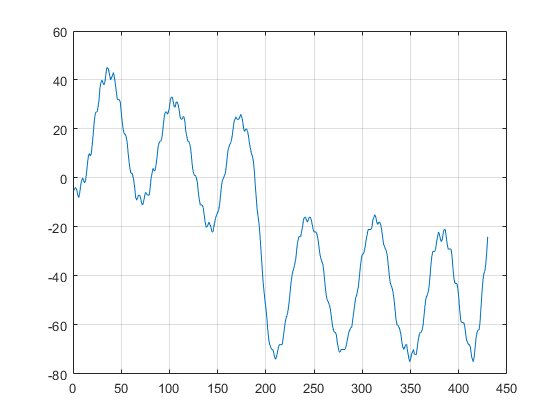

mzm = zeros(nt,10);
mzm(:,1) = ScanV(1 : nt);
for i = 2 : 10
    mzm(:,i) = ScanV(i*nt :i*nt+nt-1);
end

figure
plot(mzm(:,1))
grid on

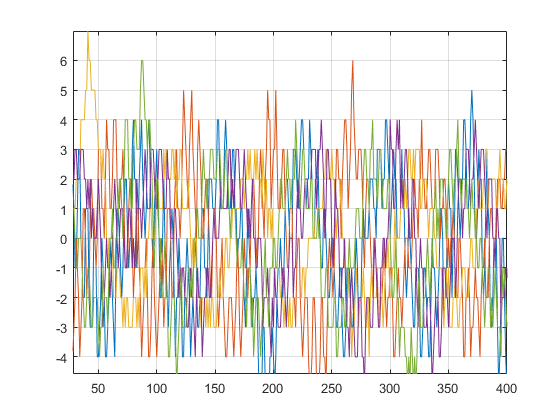


d_mzm = diff(mzm);

figure
plot(d_mzm(:,1:5));
grid on

Максимальный момент в каждом измерении

max_d_mzm = max(d_mzm)

max_d_mzm =      6     6     7     4     6     5     6     8     5     7


Математическое ожидание $\overset{-}{х} =\frac{1}{N}\bullet \sum_{i=1}^N x_i$

Mean_max_d_mzm = mean(max_d_mzm)

Mean_max_d_mzm = 6

Дисперсия 

Var_max_d_mzm = var(max_d_mzm)

Var_max_d_mzm = 1.3333

СКО

Std_max_d_mzm = std(max_d_mzm)

Std_max_d_mzm = 1.1547

CКО среденго арифметического

Std_max_d_mzm_mean = Std_max_d_mzm/sqrt(length(max_d_mzm))

Std_max_d_mzm_mean = 0.3651

Погрешность измерения ${\Delta x\;=\;S}_{\overset{-}{x} } +t$, t - коэффициент стьюдента 

t = 2.626 для 10 измерений

student_koeff = 2.626;
err_d_mzm = Std_max_d_mzm_mean*student_koeff

err_d_mzm = 0.9589

итоговая погрешность

x = $\overset{-}{x} \pm \Delta x=5\ldotp 7\pm 1\ldotp 241$

Обработка измерений маховика

nt = 455

nt = 455

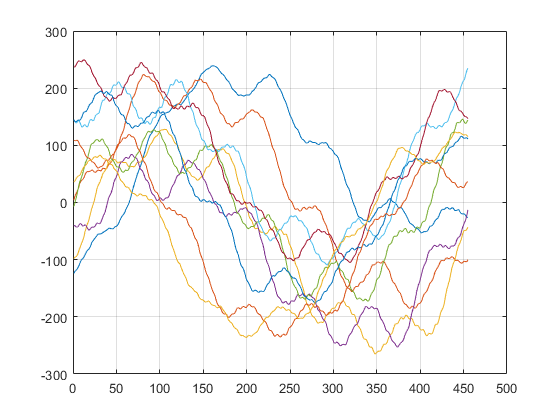

mt = zeros(nt,10);
mt(:,1) = TestMomV(1 : nt);
for i = 2 : 10
    mt(:,i) = TestMomV(i*nt :i*nt+nt-1);
end

figure
plot(mt(:,:))
grid on

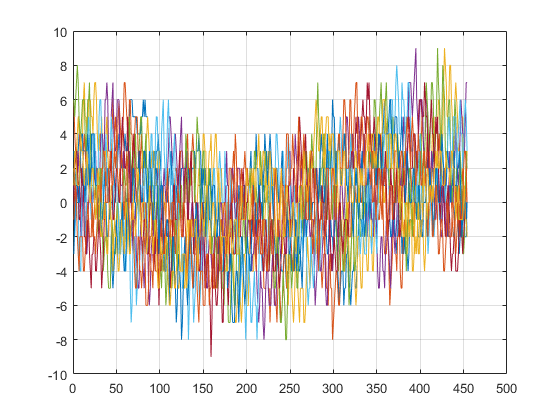


d_mt = diff(mt);

figure
plot(d_mt(:,:));
grid on

Максимальный момент в каждом измерении

max_d_mt = max(d_mt)

max_d_mt =      6     7     9     9     9     8     7     6     7     6


Математическое ожидание $\overset{-}{х} =\frac{1}{N}\bullet \sum_{i=1}^N x_i$

Mean_max_d_mt = mean(max_d_mt)

Mean_max_d_mt = 7.4000

Дисперсия 

Var_max_d_mt = var(max_d_mt)

Var_max_d_mt = 1.6000

СКО

Std_max_d_mt = std(max_d_mt)

Std_max_d_mt = 1.2649

CКО среденго арифметического

Std_max_d_mt_mean = Std_max_d_mt/sqrt(length(max_d_mt))

Std_max_d_mt_mean = 0.4000

Погрешность измерения ${\Delta x\;=\;S}_{\overset{-}{x} } +t$, t - коэффициент стьюдента 

t = 2.626 для 10 измерений

student_koeff = 2.626;
err_d_mt = Std_max_d_mt_mean*student_koeff

err_d_mt = 1.0504

итоговая погрешность

x = $\overset{-}{x} \pm \Delta x=7\ldotp 4\pm 1\ldotp 050$

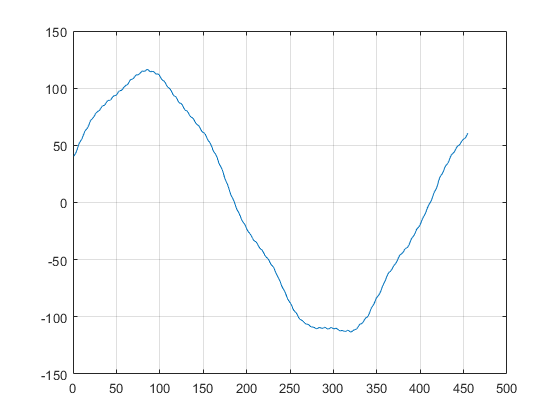

sum_mt = sum(mt, 2)/10;
sum_mt_d = diff(sum_mt);
figure
plot(sum_mt);
grid on

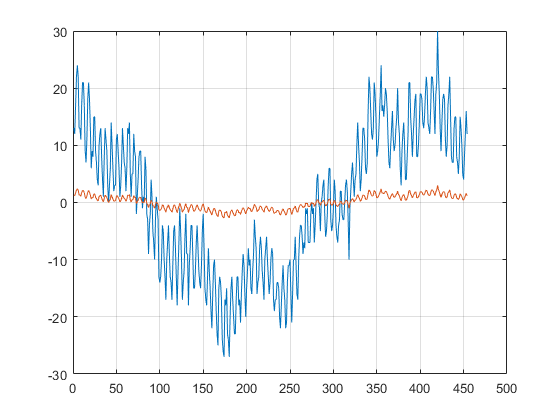


sum_dmt = sum(d_mt, 2);

figure
plot(sum_dmt)
grid on
hold on
plot(sum_mt_d)